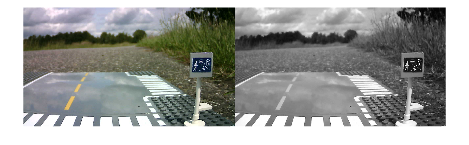

directory = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bilder\3 Rechteckige Schilder\Verkehrsberuhigter Bereich\Ackerstraße";
cd(directory);      % Arbeitsverzeichnis setzen


I = imread("Verkehrsberuhigter_Bereich-2025-06-06__9.jpg");

%imshow(I);

grayImage = rgb2gray(I);
imshowpair(I, grayImage, method = "montage");

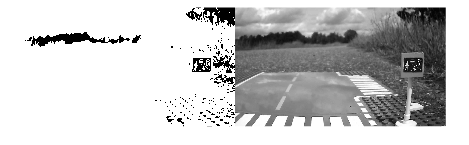

%Binärisierungsschwelle festlegen
T = 40;
C = grayImage > T;
imshowpair(C, grayImage, method = "montage");

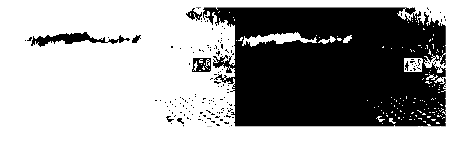

D = ~C; % Invertierung des Bildes
imshowpair(C, D, method = "montage");

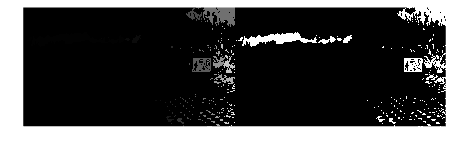

% E = imfill(D, 'holes'); 


% Objekte labeln und Eigenschaften analysieren, Achtung hintergrund
% pixel(Schwarz) werden als Hintergrund nicht als Objekt erkannt
E = bwlabel(D); % Labeling der Objekte
imshowpair(E, D, method = "montage");


stats = regionprops(E, 'BoundingBox', 'Extent'); % Eigenschaften analysieren
stats2 = regionprops(E, 'Area', 'Perimeter', 'BoundingBox', 'ConvexHull', 'Extrema');
output = I;
% Schleife durch erkannte Regionen
zaehler = 0;
% Toleranz für Eckenvereinfachung
epsilon = 0.06;

for i = 1:length(stats2)
    hull = stats2(i).ConvexHull;

    %Nur große genug Objekte weiterverarbeiten
    if stats2(i).Area > 500
        disp(i)
        % Vereinfachung des Polygons per Douglas-Peucker
        simplified = reducepoly(hull, epsilon);
        % Dreiecksprüfung mit Toleranz
        numVertices = size(simplified, 1)
        % gleiPunkte=0;
        % for j = 1:size(simplified, 1)
        %     pt1 = simplified(j, :);
        %         pt2 = simplified(mod(j, size(simplified, 1)) + 1, :);  % zyklischer Vergleich
        %     if isequal(pt1, pt2)
        %         gleiPunkte=1;
        %     end
        % end
        if numVertices ==5
            % Möglicherweise ein Dreieck
            output = insertShape(output, 'Polygon', simplified, ...
                'Color', 'green', 'LineWidth', 10);
        end
    end
end

     4



numVertices = 6

    23



numVertices = 7

    51



numVertices = 7

   108



numVertices = 6

   145



numVertices = 6

   182



numVertices = 5

   225



numVertices = 6

   290



numVertices = 7

   309



numVertices = 7

   356



numVertices = 7

   399



numVertices = 7

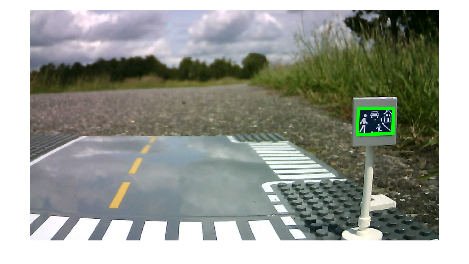


imshow(output);





% zaehler = 0;
% % Erkennung von Dreiecken
% imshow(I); hold on;
% for i = 1:numel(stats2)
%     if abs(stats2(i).BoundingBox(3) - stats2(i).BoundingBox(4)) > 0.1 % Breite und Höhe vergleichen
%         if (stats2(i).BoundingBox(3)>10) && (stats2(i).BoundingBox(4)>10)
%         thisBB = stats2(i).BoundingBox;
%         rectangle('Position', thisBB, 'EdgeColor', 'r', 'LineWidth', 2);
%         zaehler = zaehler + 1;
%         end
%     end
% end
% figure
% imshow(I); hold on;
% 
% for i = 1:numel(stats2)
%     thisBB = stats2(i).BoundingBox;
%     rectangle('Position', thisBB, 'EdgeColor', 'r', 'LineWidth', 2);
% end
% 
% title('Erkannte BoundingBoxen'); hold off;